# Sample 9-2

## 離散ウェーブレット変換

ブロックDCTのフィルタバンク実装

画像処理特論

村松 正吾 

動作確認: MATLAB R2020a

## Discrete wavelet transform

Filter bank implementation of block DCT

Advanced Topics in Image Processing

Shogo MURAMATSU

Verified: MATLAB R2020a

### 準備

(Preparation)

close all

## ブロックサイズの設定

(Settings of block size)

% # of channels
nChs = 4;

## 入力信号の生成

(Generation of input)

% Input signal
u = rand(1,3*nChs);
u = [0 u zeros(1,nChs-1)];

### 並列フィルタバンク実装

(Parallel filter bank implementation)

% DCT matrix
P =  dctmtx(nChs);

% IDCT matrix
Q = P.';

% Analysis process
s = cell(nChs,1);
for iCh = 1:nChs
    hk = fliplr(P(iCh,:));
    % Decimation
    s{iCh} = downsample(conv(hk,u),nChs); 
end
s = cell2mat(s);

% Synthesis process
v = 0;
for iCh = 1:nChs
    fk = Q(:,iCh);
    % Interpolation
    vk = conv(fk,upsample(s(iCh,:),nChs));
    v = v + vk;
end

## 信号表示

(Signal display)

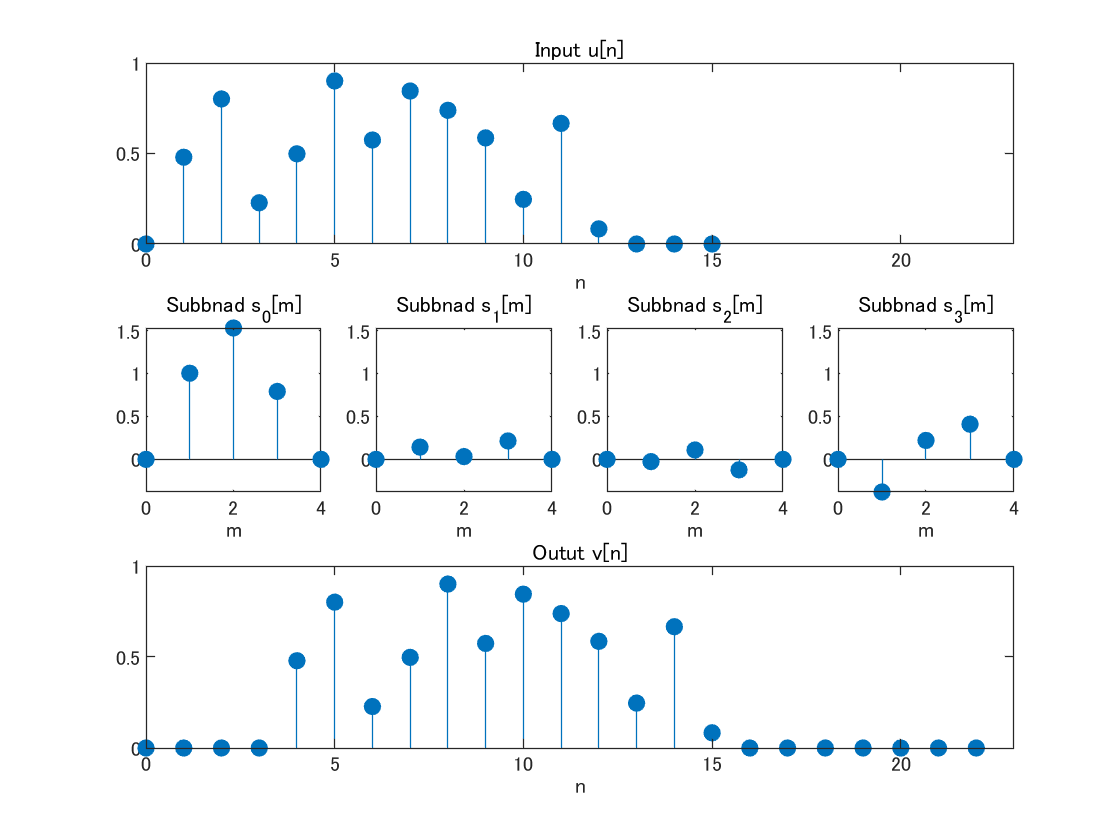

figure(1)
subplot(3,nChs,1:nChs)
stem(0:length(u)-1,u,'filled')
title('Input u[n]')
xlabel('n')
ax = gca;
ax.XLim =[ 0 length(v)];

for iCh = 1:nChs
    subplot(3,nChs,nChs+iCh)
    stem(0:size(s,2)-1,s(iCh,:),'filled')
    title(['Subbnad s_' num2str(iCh-1) '[m]'])
    xlabel('m')
    ax = gca;
    ax.YLim =[ min(s(:)) max(s(:)) ];
end

subplot(3,nChs,2*nChs+(1:nChs))
stem(0:length(v)-1,v,'filled')
title('Outut v[n]')
xlabel('n')
ax = gca;
ax.XLim =[ 0 length(v)];

### 合成フィルタのインパルス応答（基底ベクトル）

(Impluse responses of synthesis filters; basis vectors)

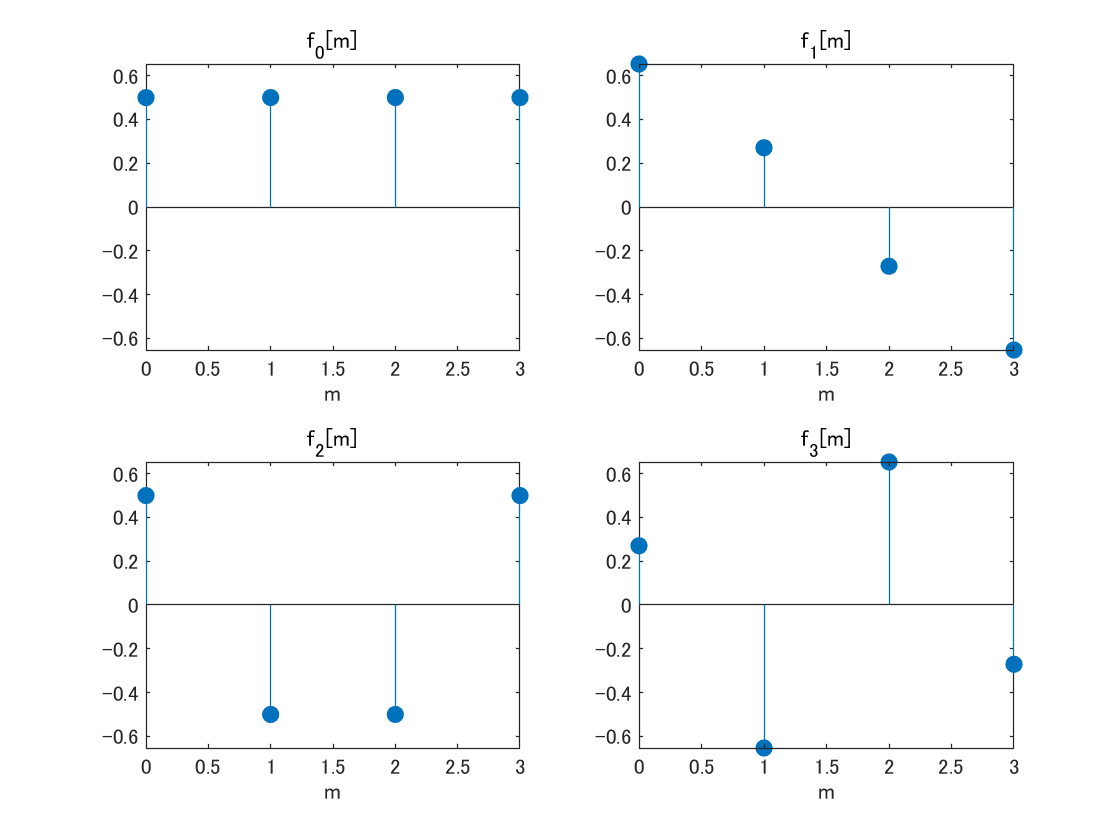

figure(2)
for iCh = 1:nChs
    fk = Q(:,iCh);
    subplot(nChs/2,2,iCh)
    stem(0:length(fk)-1,fk,'filled')
    title([ 'f_' num2str(iCh-1) '[m]' ])
    xlabel('m')
    ax = gca;
    ax.YLim =[ min(Q(:)) max(Q(:)) ];
end

### 合成フィルタの周波数応答（基底ベクトル）

(Frequency responses of synthesis filters; basis vectors)

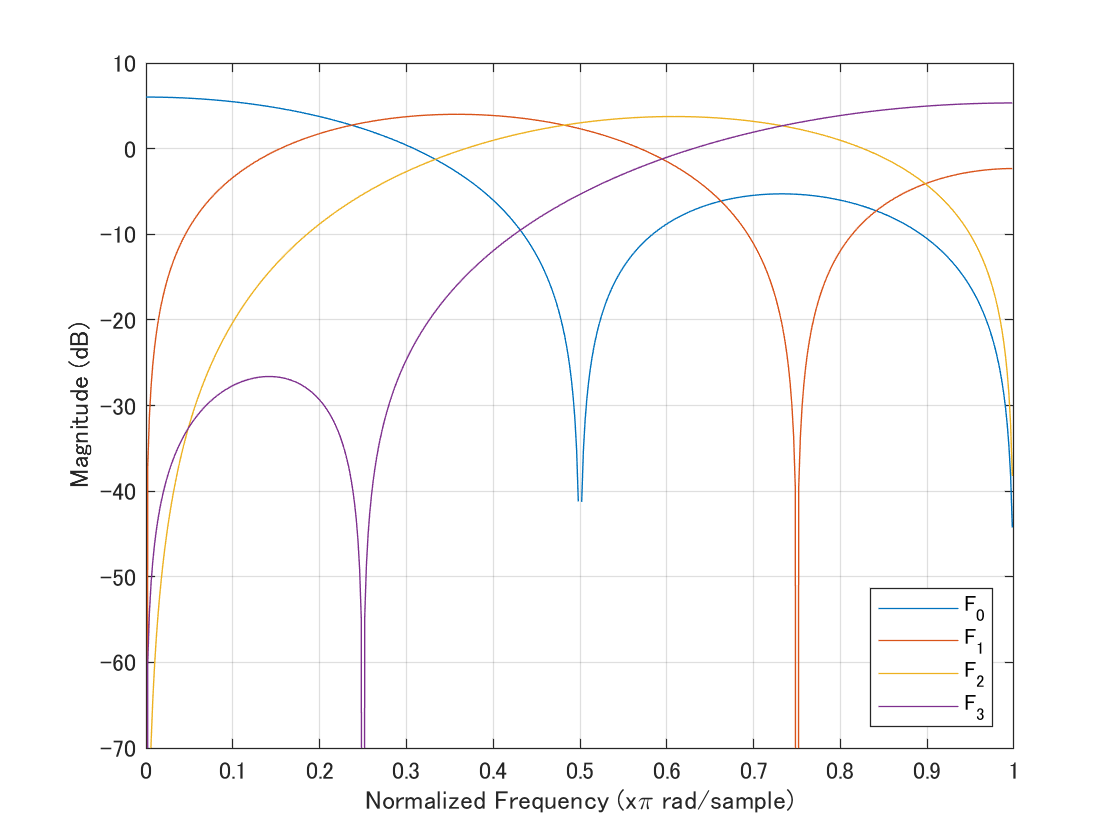

figure(3)
fftPoints = 512;
F = zeros(fftPoints,nChs);
legends = cell(nChs,1);
for iCh = 1:nChs
    fk = Q(:,iCh); 
    if iCh == 1
        [F(:,iCh),W] = freqz(fk,1,fftPoints);
    else
        F(:,iCh) = freqz(fk,1,fftPoints);
    end
    legends{iCh} = [ 'F_' num2str(iCh-1) ];
end
plot(W/pi,20*log10(abs(F)))
axis([0 1 -70 10])
xlabel('Normalized Frequency (x\pi rad/sample)')
ylabel('Magnitude (dB)')
legend(legends,'Location','southeast')
grid on

### ポリフェーズ行列実装

(Polyphase matrix implemenation)

分析合成処理 (Analysis and synthesis process)

% Input Signal
u = [zeros(1,nChs-1) u 0 ];
disp(u)

  1 列から 18 列

         0         0         0         0    0.4795    0.8013    0.2278    0.4981    0.9009    0.5747    0.8452    0.7386    0.5860    0.2467    0.6664    0.0835         0         0

  19 列から 20 列

         0         0




% Serial/Parallel conversion
x = cell(nChs,1);
for iCh = 1:nChs
    x{iCh} = downsample(u,nChs,iCh-1);
end
x = cell2mat(x);
disp(x)

         0    0.4795    0.9009    0.5860         0
         0    0.8013    0.5747    0.2467         0
         0    0.2278    0.8452    0.6664         0
         0    0.4981    0.7386    0.0835         0




% Analysis process w/ the polyphase matrix
E = P;
s = E*x;
disp(s)

         0    1.0034    1.5297    0.7913         0
         0    0.1431    0.0328    0.2147         0
         0   -0.0258    0.1098   -0.1218         0
         0   -0.3797    0.2206    0.4101         0



% Synthesis process w/ the polyphase matrix
R = Q;
y = R*s;
disp(y)

         0    0.4795    0.9009    0.5860         0
         0    0.8013    0.5747    0.2467         0
         0    0.2278    0.8452    0.6664         0
         0    0.4981    0.7386    0.0835         0



% Parallel/Serial conversion
v = 0;
for iCh = 1:nChs
    v = v + upsample(y(iCh,:),nChs,iCh-1);
end
disp(v)

  1 列から 18 列

         0         0         0         0    0.4795    0.8013    0.2278    0.4981    0.9009    0.5747    0.8452    0.7386    0.5860    0.2467    0.6664    0.0835         0         0

  19 列から 20 列

         0         0



© Copyright, Shogo MURAMATSU, All rights reserved.